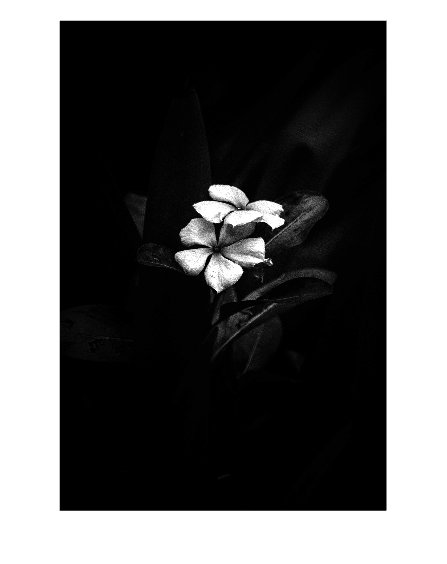

img = imread("pexels-sharath-giri-3849160.jpg");
gs = im2gray(img);
gsAdj = imadjust(gs);
imshow(gsAdj);

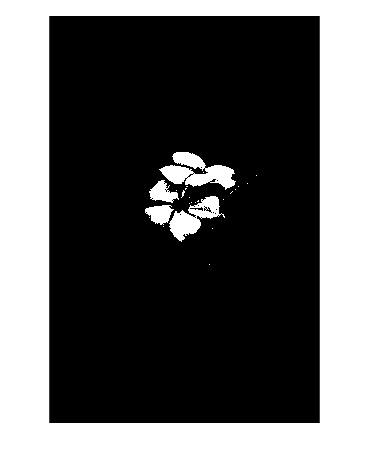

BW = gsAdj > 255/2;
imshow(BW);

Now reading images\Street Photography_3.jpeg
Now reading images\Street Photography_4.jpeg
Now reading images\Street Photography_5.jpeg
Now reading images\Street Photography_6.jpeg
Now reading images\Street Photography_7.jpeg
Now reading images\Street Photography_8.jpeg


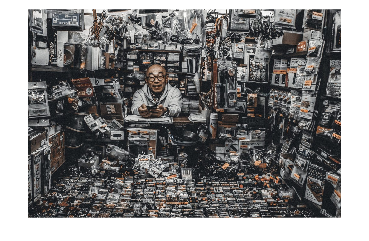

%code to read multiple files in matlab
% Define the directory containing image files
myFolder = 'images';

% Define the file pattern for either JPG or BMP files
filePattern = fullfile(myFolder, '*.jpeg'); % Change to '*.bmp' if needed

% List image files that match the pattern
jpegFiles = dir(filePattern);

% Loop through the image files
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    imageArray = imread(fullFileName);
    imshow(imageArray);  % Display image.
    drawnow; % Force display to update immediately.
end